clc;
clear all;
warning off;
%     A1     b1      A2      b2      A5      b5      Tp      Tf     Tvl
%     Tv0    yita    S1      S2      S3      S4      k0      k1     k2      k3
lb = [
      0       %A1
      0       %b1
      0       %A2
      0       %b2
      0       %Tp
      0       %Tf0
      0       %Tvl
      0       %Tv0
      0.85    %yita
     ]; 

ub = [
      0.8     %A1
      0.8     %b1
      0.8     %A2
      0.8     %b2
      10       %Tp
      5       %Tf0
      15      %Tvl
      5      %Tv0
      0.95    %yita
     ];    

Npara = length(lb); 

A1   = 0.3         ; A2   = 0.3        ;
b1   = 0.3        ; b2   = 0.3           ;
Tp   = 5           ; Tf0  = 1             ;
Tvl  = 8            ; Tv0  = 2             ;
st   = 0.19          ; yita = 0.95          ;

para_init = [A1,b1,A2,b2,...
            Tp,Tf0,Tvl,Tv0,...
            yita];

%% ==================== 1. conditions_setup ============================
meanangle    = 9.6;
averageangle = 7;
conditions   = input_condition(meanangle,averageangle);
airfoildata  = input_afdata;

CFDdatapath = 're1e6_9.6_f0.6.txt';

%% ==================== 2. variable reshape ============================
setcase.meanangle    = meanangle;
setcase.averageangle = averageangle;
setcase.conditions   = conditions;
setcase.airfoldata   = airfoildata;
setcase.CFDdatapath  = CFDdatapath;

para_local_DTW = run_optimal_DTW(para_init,Npara,lb,ub,setcase);

===== 动态失速BL模型参数优化开始【CFD拟合+面积相似度】 =====

单目标优化:
9 变量
1 非线性不等式约束

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible
正在使用 'Processes' 配置文件启动并行池(parpool)...
已连接到具有 16 个工作进程的并行池。

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1          12675       1.27157            0      0
    2          25094       1.27076            0      0
    3          37513       1.27066            0      0
优化结束: 适应度值的平均变化小于 options.FunctionTolerance 且约束违反值小于 options.ConstraintTolerance。
===== 优化完成！最优适应度值 = 1.27065997 =====

==================== 原始参数 ↔ 优化后最优参数 对比表 ====================
原始适应度=3.126289 | 优化适应度=1.270660
   A1 : 原始值=0.300000 | 优化值=0.344044
   b1 : 原始值=0.300000 | 优化值=0.442556
   A2 : 原始值=0.300000 | 优化值=0.591439
   b2 : 原始值=0.300000 | 优化值=0.335239
   Tp : 原始值=5.000000 | 优化值=1.914362
  Tf0 : 原始值=1.000000 | 优化值=2

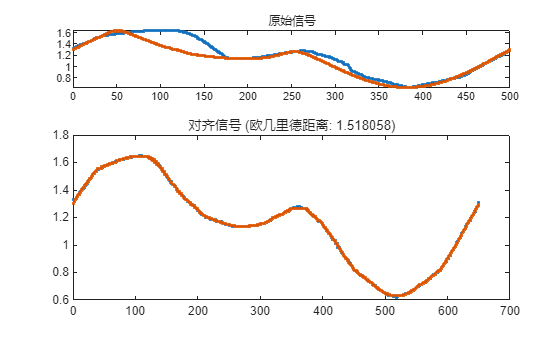

ans = 1.5181

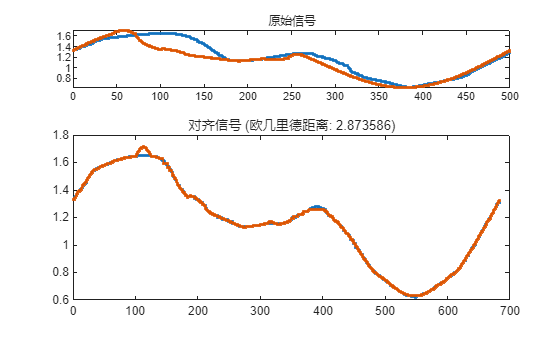

ans = 2.8736

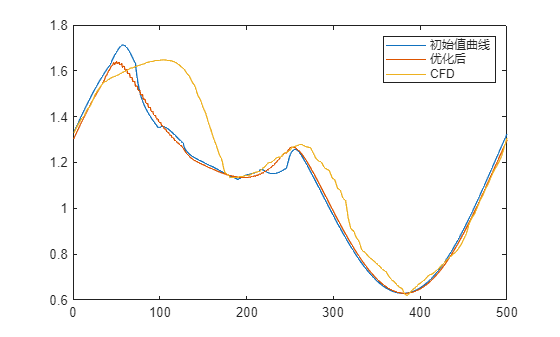

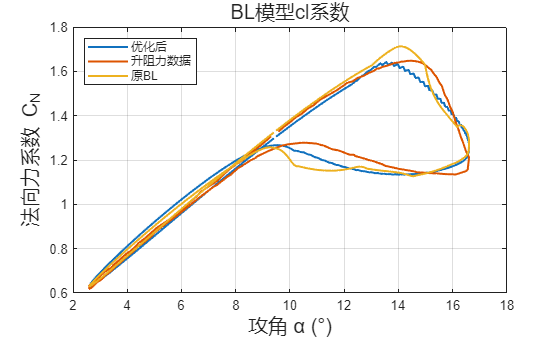

compare_optimal_result_DTW(para_local_DTW,para_init,setcase);

para_local_GZ = run_optimal_GZ(para_init,Npara,lb,ub,setcase);

===== 动态失速BL模型参数优化开始【CFD拟合+面积相似度】 =====

单目标优化:
9 变量
1 非线性不等式约束

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1          12675      0.413659            0      0
    2          25094      0.412361            0      0
    3          37513      0.412007            0      0
优化结束: 适应度值的平均变化小于 options.FunctionTolerance 且约束违反值小于 options.ConstraintTolerance。
===== 优化完成！最优适应度值 = 0.41200697 =====

==================== 原始参数 ↔ 优化后最优参数 对比表 ====================
原始适应度=0.081873 | 优化适应度=0.087183
   A1 : 原始值=0.300000 | 优化值=0.799334
   b1 : 原始值=0.300000 | 优化值=0.799945
   A2 : 原始值=0.300000 | 优化值=0.470238
   b2 : 原始值=0.300000 | 优化值=0.797107
   Tp : 原始值=5.000000 | 优化值=2.777438
  Tf0 : 原始值=1.000000 | 优化值=0.460467
  Tvl : 原始值=8.000000 | 优化值=14.999704
  Tv0 : 原始值=2.0

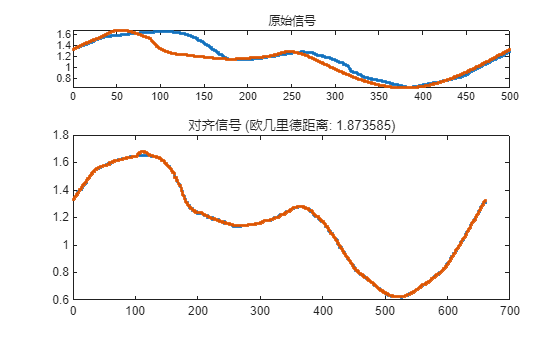

ans = 1.8736

ans = 2.8736

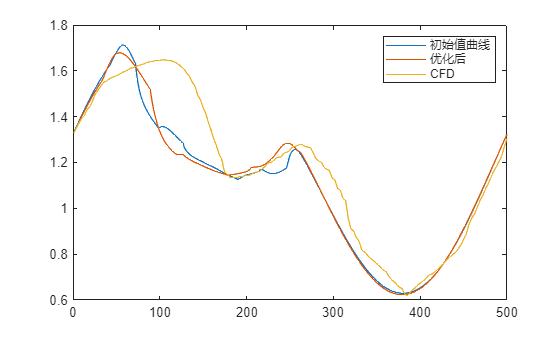

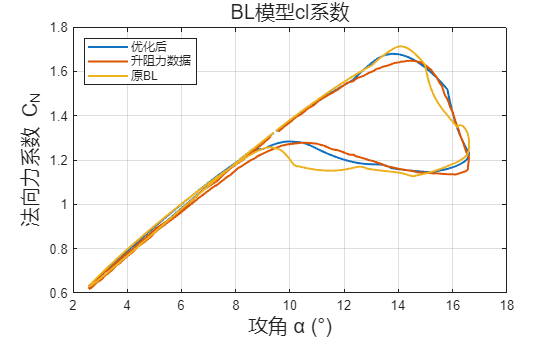

compare_optimal_result_GZ(para_local_GZ,para_init,setcase);

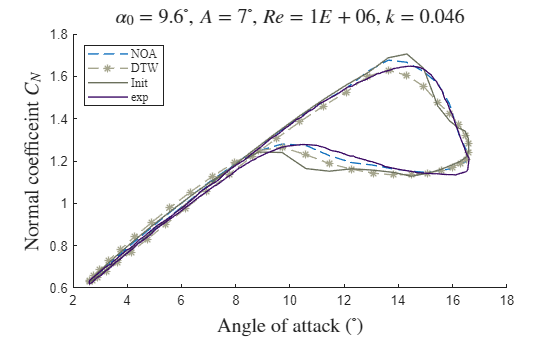


load("data_collection_DTW.mat");
DTW_data = [DTW_data(1:10:end,:)
            DTW_data(1,:)];
load("data_collection_GZ.mat");
GZ_data = [GZ_data(1:10:end,:)
            GZ_data(1,:)];

init_data = [init_data(1:10:end,:)
             init_data(1,:)];

exp_data = [exp_data
            exp_data(1,:)];

figure
fontsize = 15;
line = 1;
% plot(ARE_data(:,1) ,ARE_data(:,2) ,'o--','LineWidth',line,'Color',[237/255 179/255 39/255])
% hold on
% plot(DTW_data(:,1) ,DTW_data(:,2) ,'*--','LineWidth',line,'Color',[243/255 126/255 120/255])
% plot(MSE_data(:,1) ,MSE_data(:,2) ,'x--','LineWidth',line,'Color',[65/255  137/255 200/255])
% plot(init_data(:,1),init_data(:,2),      'LineWidth',line,'Color',[141/255 90/255  133/255])
% plot(exp_data(:,1) ,exp_data(:,2) ,      'LineWidth',line,'Color',[58/255  9/255   100/255])

hold on
plot(GZ_data(:,1) ,GZ_data(:,2) ,'--','LineWidth',line)
plot(DTW_data(:,1) ,DTW_data(:,2) ,'*--','LineWidth',line,'Color',[165/255 165/255 141/255])
plot(init_data(:,1),init_data(:,2),      'LineWidth',line,'Color',[107/255 112/255 92/255])
plot(exp_data(:,1) ,exp_data(:,2) ,      'LineWidth',line,'Color',[58/255  9/255   100/255])

legend('NOA','DTW',"Init",'exp','Location', 'northwest','FontName', 'Times New Roman');
title(sprintf('$\\alpha_0=%.1f^\\circ$, $A=%d^\\circ$, $Re=%.0E$, $k=%.3f$', meanangle, averageangle,conditions.Re,conditions.k), ...
       'Interpreter', 'latex', ...    
       'FontName', 'Times New Roman', ...  
       'FontSize', fontsize);

xlabel('Angle of attack ($^\circ$)', ... 
       'Interpreter', 'latex', ...    
       'FontName', 'Times New Roman', ...  
       'FontSize', fontsize); 

ylabel('Normal coefficeint $C_N$', ... 
       'Interpreter', 'latex', ...    
       'FontName', 'Times New Roman', ...  
       'FontSize', fontsize);
saveas(gcf, ['opt_compare','.png']);
exportgraphics(gcf,'opt_compare.pdf','ContentType', 'vector')